clear all;

## Чтение файла "proto.txt"

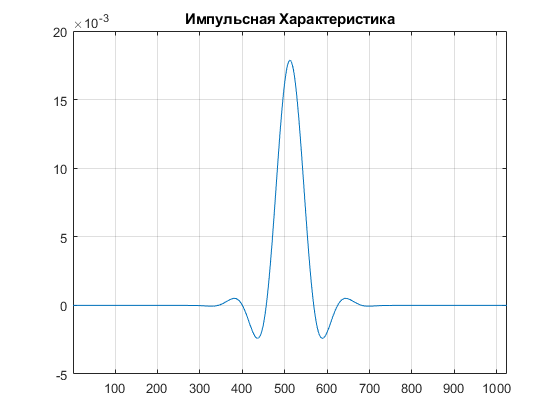

text = fopen('proto.txt');
k = 0;
while ~feof(text)
    tline = fgetl(text);
    h(k + 1) = str2double(tline);
    k = k + 1;
end
fclose(text);
plot(1:length(h), h); title('Импульсная Характеристика'); grid on; xlim([1, length(h)]); ylim([-5*(10^-3), 20*(10^-3)]);

clear tline text k;

## Исходные данные

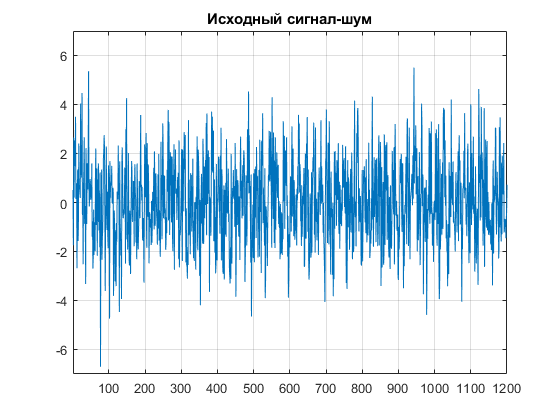

L = 32; Fs = 1000; f0 = 50; T = 1 / Fs; max = 1200; t = (0 : (max-1))*T;
x = awgn(sin(2*pi*f0*t),-7,'measured');
plot(x); title('Исходный сигнал-шум'); grid on;
xlim([1, length(x)]); ylim([-7,7]);

clear max t;

## Програмная интерполяция

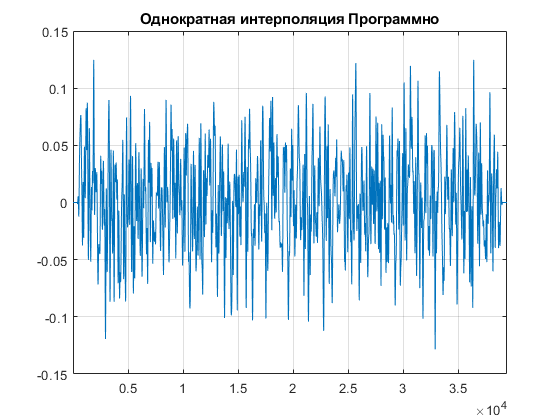

ypro = conv(h, upsample(x, L));
plot(ypro); title('Однократная интерполяция Программно');
grid on; xlim([1, length(ypro)]);

## Первый этап интерполяции

x_copy = x; w = zeros(1, L*length(x_copy));
for (i = 1 : length(x_copy)) w((i - 1)*L + 1) = x_copy(i); end
clear x_copy i;

## Второй этап интерполяции

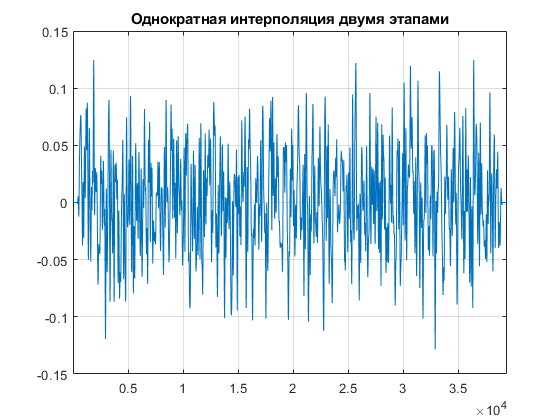

h_copy = h; w_copy = w; Nout = length(h_copy) + length(w_copy) - 1;
h_copy((length(h_copy)+1) : Nout) = 0; w_copy((length(w_copy)+1) : Nout) = 0;
for (n = 1 : Nout) y(n) = sum(w_copy(1:n).*h_copy(n - (0:(n-1)))); end
plot(y); title('Однократная интерполяция двумя этапами');
grid on; xlim([1, length(y)]); clear h_copy w_copy Nout n w;

## Общая однократная интерполяция

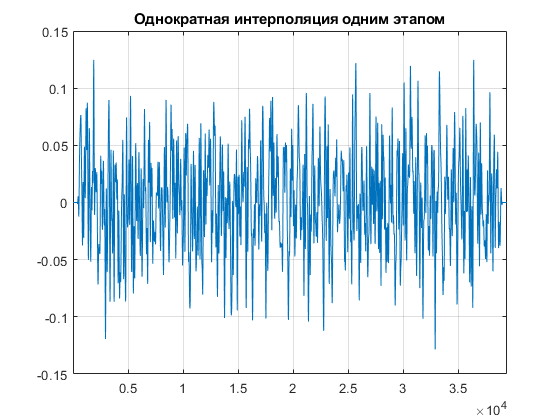

x_copy = x; h_copy = h;
x_copy((end + 1) : (length(x_copy)*L)) = 0;
Nout = length(h_copy) + length(x_copy) - 1;
h_copy((length(h_copy)+1) : Nout) = 0;
x_copy((length(x_copy)+1) : Nout) = 0;
for (n = 1 : Nout)
    yc(n) = sum(h_copy(n - (0 : L : (n - 1))).*x_copy((0 : L : (n - 1))/L + 1));
end
plot(yc); title('Однократная интерполяция одним этапом');
grid on; xlim([1, length(yc)]);

clear x_copy h_copy Nout n;

## Полифазная интерполяция

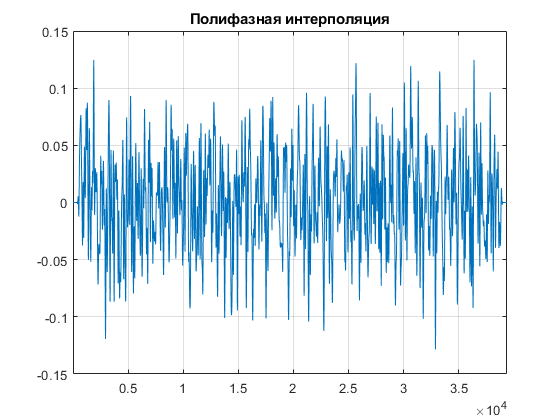

h_copy = h; x_copy = x;
for (i = 1 : L)
    for (k = 1 : (length(h_copy)/L))
        h_matr(i, k) = h_copy((k - 1)*L + i);
    end
end
clear i j k;
Nout = size(h_matr, 2) + length(x_copy) - 1;
x_copy((end+1) : Nout) = 0; zeroh = zeros(L, Nout - size(h_matr, 2));
h_matr = [h_matr zeroh];
for (i = 1 : L)
    for (j = 1 : Nout)
        y_matr(i, j) = sum( h_matr(i, 1 + (0 : (j - 1))).*x_copy(j - (0 : (j - 1))) );
    end
end
clear i j;
n = 1;
for (i = 1 : Nout)
    for (j = 1 : L)
        poliy(n) = y_matr(j, i);
        n = n + 1;
    end
end
plot(poliy); title('Полифазная интерполяция'); grid on; xlim([1, length(poliy)]);

clear h_copy x_copy i k h_matr Nout zeroh j y_matr n;

## Разница Програмной и Ручной

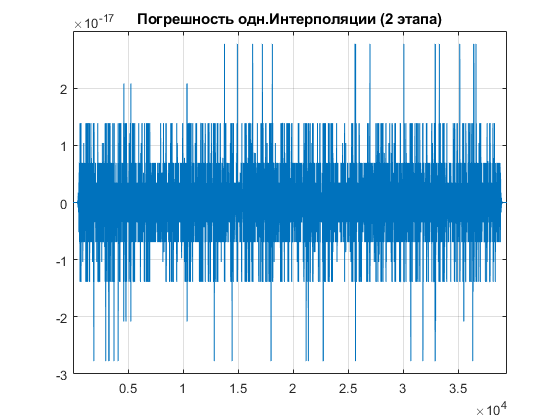

ypro_copy = ypro;
y_copy = y;
yc_copy = yc;
poliy_copy = poliy;
for (i = 1 : length(y_copy))
    dev_y(i) = ypro_copy(i) - y_copy(i);
end
for (i = 1 : length(yc_copy))
    dev_yc(i) = ypro_copy(i) - yc_copy(i);
end
for (i = 1 : length(poliy_copy))
    dev_poliy(i) = ypro_copy(i) - poliy_copy(i);
end
plot(dev_y); title('Погрешность одн.Интерполяции (2 этапа)');
grid on; xlim([1, length(dev_y)]);

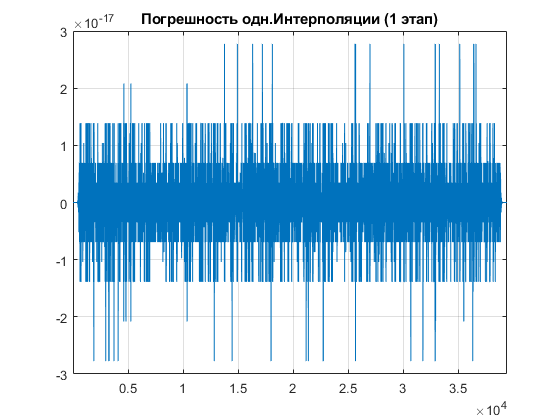

plot(dev_yc); title('Погрешность одн.Интерполяции (1 этап)');
grid on; xlim([1, length(dev_yc)]);

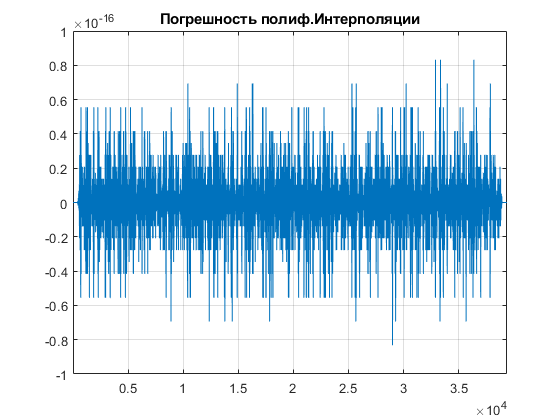

plot(dev_poliy); title('Погрешность полиф.Интерполяции');
grid on; xlim([1, length(dev_poliy)]);

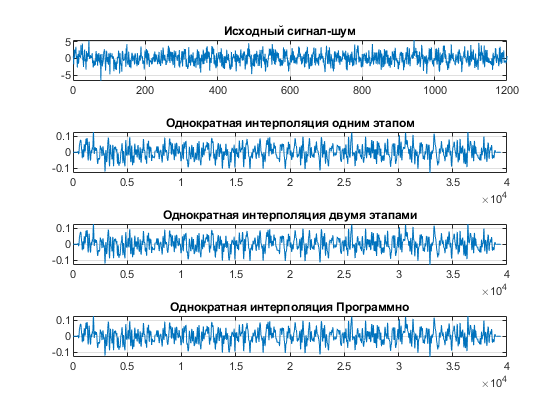


figure
subplot(4,1,1);
plot(x); title('Исходный сигнал-шум'); grid on;
subplot(4,1,2);
plot(yc); title('Однократная интерполяция одним этапом'); grid on;
subplot(4,1,3);
plot(y); title('Однократная интерполяция двумя этапами'); grid on;
subplot(4,1,4);
plot(ypro); title('Однократная интерполяция Программно'); grid on;

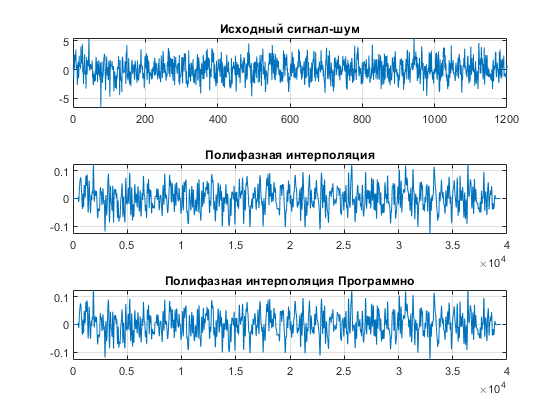

figure
subplot(3,1,1);
plot(x); title('Исходный сигнал-шум'); grid on;
subplot(3,1,2);
plot(poliy); title('Полифазная интерполяция'); grid on;
subplot(3,1,3);
plot(ypro); title('Полифазная интерполяция Программно'); grid on;


clear ypro_copy y_copy yc_copy poliy_copy i dev_y dev_yc dev_poliy ans;